# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0194    0.0102   -0.0147   -0.0134   -0.0195   -0.0161   -0.0203   -0.0200   -0.0191   -0.0195   -0.0196   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194   -0.0194
   -0.0765   -0.0769   -0.1134   -0.0759   -0.0765   -0.0755   -0.0765   -0.0751   -0.0768   -0.0765   -0.0764   -0.0766   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0.0765   -0


% Oefening 4
e1 = zeros(n, 1);
e2 = zeros(n, 1);

[Q1,~] = klGS(A)

Q1 =    -0.0194    0.0591    0.0185    0.0475   -0.0029    0.1050   -0.0606   -0.0777    0.0612   -0.0559   -0.1939   -0.0173    0.0488   -0.1695    0.0074   -0.1245   -0.0281    0.0495    0.0843   -0.0759   -0.0306    0.0853   -0.0031    0.1354    0.0943    0.0567   -0.0385   -0.0150   -0.0242   -0.0177   -0.0189   -0.0185   -0.0186   -0.0185   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186   -0.0186
   -0.0765   -0.0007   -0.1472    0.0055    0.0001    0.0338    0.0050    0.1863   -0.0750    0.0325    0.1051   -0.0660    0.1071    0.0295   -0.0037    0.0158   -0.1187   -0.1110   -0.0236   -0.0215    0.0848   -0.0365    0.0532    0.0261   -0.0550    0.1008   -0.0766   -0.0483   -0.0475   -0.0521   -0.0505   -0.0502   -0.0499   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -0.0500   -

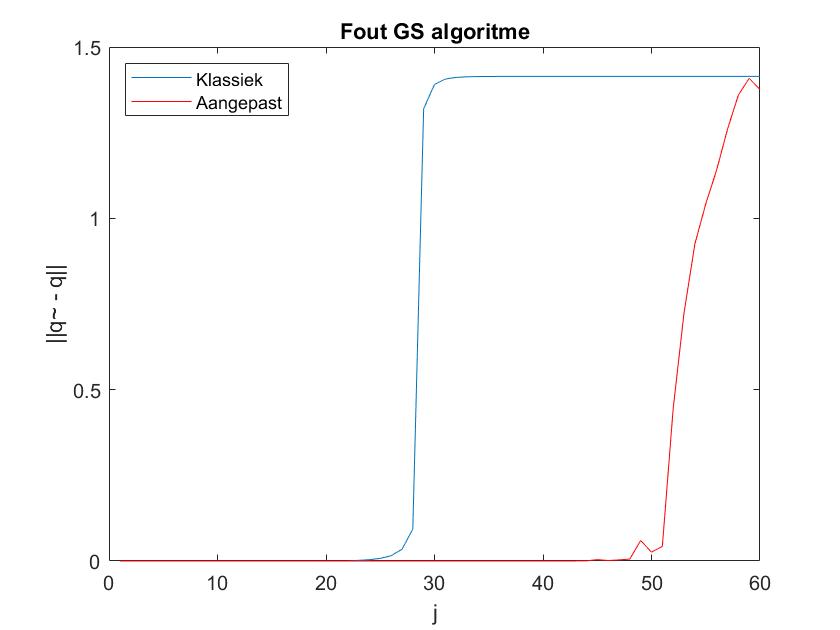

[Q2,~] = modGS(A);

for j = 1:n
    e1(j, 1) = norm(Q1(:,j)-Q(:,j));
    e2(j, 1) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')

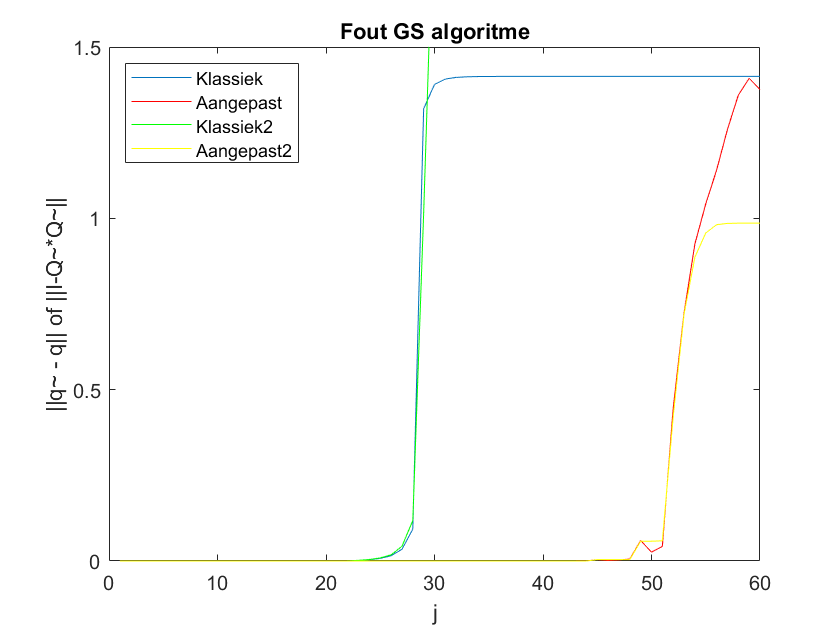


% Oefening 8
orth1 = zeros(n, 1);
orth2 = zeros(n, 1);

for j = 1:n
    orth1(j, 1) = norm(eye(j) - Q1(:,1:j)'*Q1(:,1:j));
    orth2(j, 1) = norm(eye(j) - Q2(:,1:j)'*Q2(:,1:j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold on
plot(orth1, 'Color', 'g')
hold on
plot(orth2,'Color','y')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q|| of ||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Klassiek2', 'Aangepast2', 'Location','northwest')
axis([0 60 0 1.5])

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0493   -0.0200   -0.0549
    0.0666    0.0626    0.0863
   -0.0288   -0.0130   -0.0298
   -0.0105    0.0207   -0.0106
   -0.0911   -0.0569   -0.0706
   -0.1160   -0.0077   -0.1250
    0.1664    0.1525    0.1712
   -0.0420   -0.0533   -0.0497
    0.0795    0.0918    0.0902
    0.1520    0.1466    0.1212


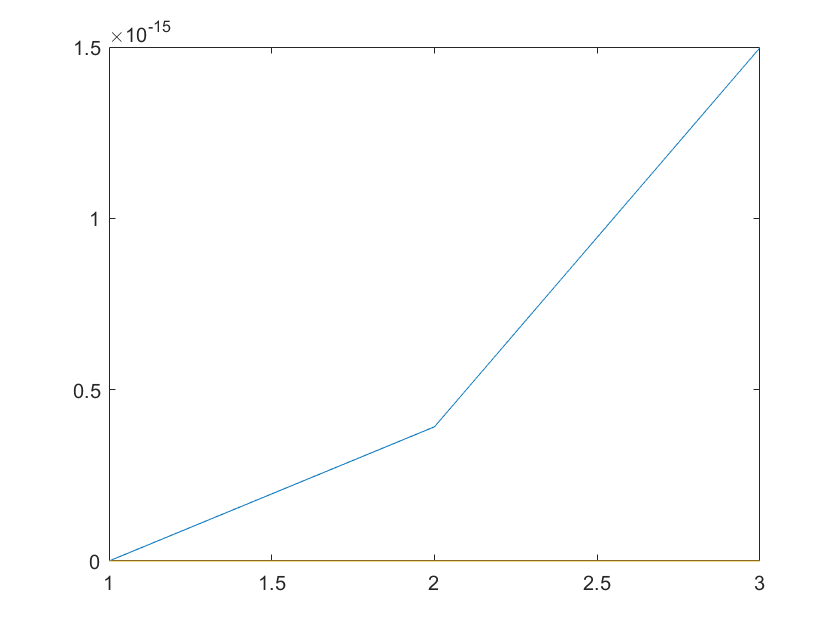


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

[V,~] = qr(rand(n));
V = 10*rand*V;

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A;

K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


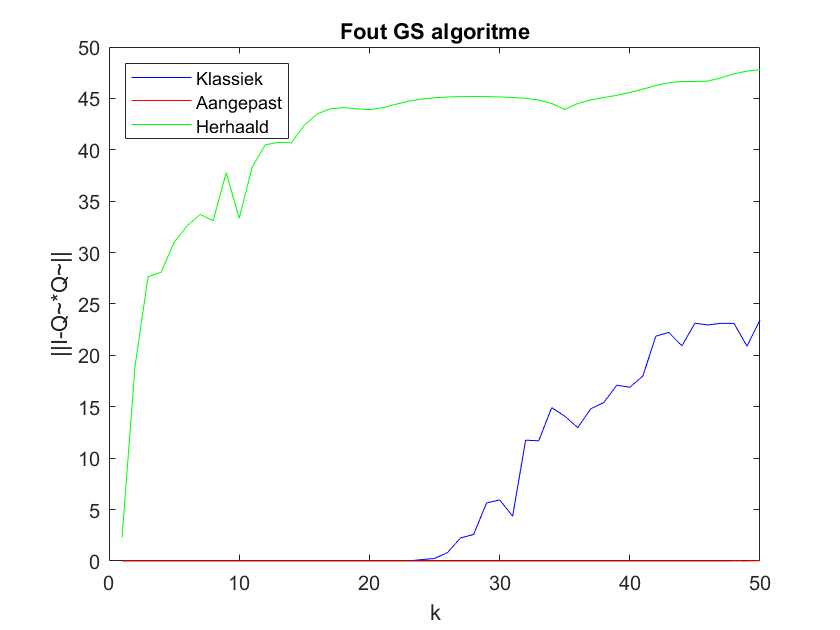


% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1;

Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2;

Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3;

orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1;

orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2;

orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3;

plot(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000, 100);
n = length(A);
m = 100;
v = rand(n,1);

ritzvaluesiterations = zeros(m, 6);
for i=1:m
    [V,H] = Arnoldi(A,v,i);
    Hn = H(1:i, :);
    [~, ritzvalues] = eigs(Hn);
    for k=1:length(ritzvalues)
        ritzvaluesiterations(i, k) = ritzvalues(k, k);
    end
end

[V,H] = Arnoldi(A,v,m);

colors = ['g', 'b', 'c', 'r', 'm', 'y']

colors = 'gbcrmy'

eigenvalues = zeros(6, 1);
[~, eigenvaluesdiagonal] = eigs(A);
for eigenvalue=1:6
    eigenvalues(eigenvalue) = eigenvaluesdiagonal(eigenvalue, eigenvalue);
    plot(real(eigenvalues(eigenvalue)), imag(eigenvalues(eigenvalue)), 'x', "MarkerSize",20, "Color", colors(eigenvalue))
    hold on
end

eigenvalues

eigenvalues = 	1.0e+02 *

   3.1629 + 0.0000i
   0.1041 + 0.0223i
   0.1041 - 0.0223i
  -0.1059 + 0.0105i
  -0.1059 - 0.0105i
   0.1060 + 0.0016i


ritzvaluesiterations;
Hn = H(1:m, :);
[~, ritzvalues] = eigs(Hn);

ritz1 = ritzvaluesiterations(:, 1)

ritz1 =   235.1698
  316.1621
  316.2918
  316.2921
  316.2921
  316.2921
  316.2921
  316.2921
  316.2921
  316.2921


ritz2 = ritzvaluesiterations(:, 2)

ritz2 =    0.0000 + 0.0000i
  -0.3186 + 0.0000i
  -0.0636 + 1.2655i
   3.9712 + 0.0000i
   5.0837 + 0.0000i
   7.1845 + 0.0000i
  -5.9992 + 3.2685i
  -6.5240 + 3.1272i
  -7.6604 + 3.5287i
  -7.6916 + 2.8280i


ritz3 = ritzvaluesiterations(:, 3)

ritz3 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0636 - 1.2655i
  -1.7384 + 2.1540i
  -3.2295 + 0.0000i
  -5.3410 + 3.8543i
  -5.9992 - 3.2685i
  -6.5240 - 3.1272i
  -7.6604 - 3.5287i
  -7.6916 - 2.8280i


ritz4 = ritzvaluesiterations(:, 4)

ritz4 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.7384 - 2.1540i
  -0.6847 + 2.4005i
  -5.3410 - 3.8543i
   5.8294 + 2.4407i
   5.7080 + 4.0116i
  -2.1624 + 7.1559i
   5.5727 + 5.6311i


ritz5 = ritzvaluesiterations(:, 5)

ritz5 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.6847 - 2.4005i
   1.9839 + 5.5313i
   5.8294 - 2.4407i
   5.7080 - 4.0116i
  -2.1624 - 7.1559i
   5.5727 - 5.6311i


ritz6 = ritzvaluesiterations(:, 6)

ritz6 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.9839 - 5.5313i
   0.5407 + 6.0493i
  -1.3013 + 6.6280i
   3.8293 + 5.7198i
  -2.5402 + 6.9180i


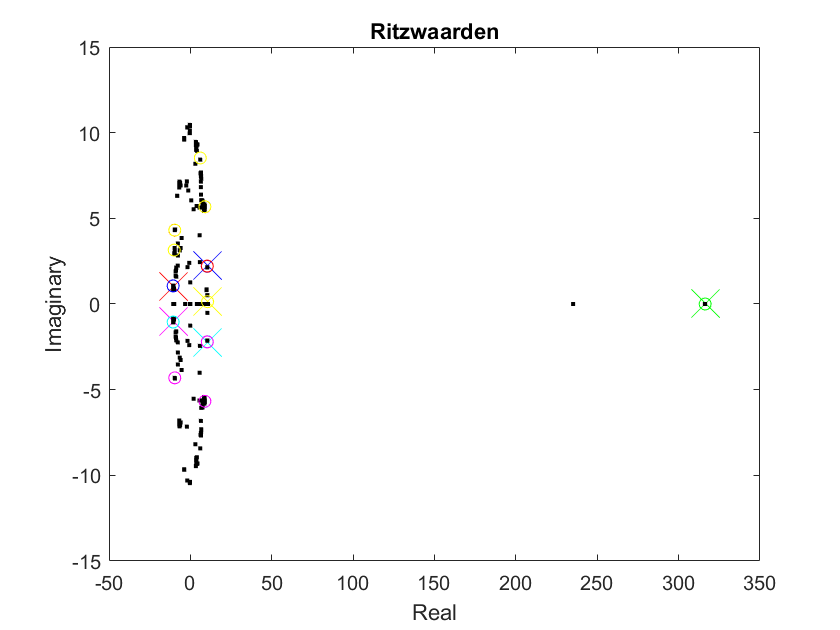

for k=1:100
    if k < 91
        plot(real(ritz1(k)), imag(ritz1(k)), '.', 'Color', 'k')
        plot(real(ritz2(k)), imag(ritz2(k)), '.', 'Color', 'k')
        plot(real(ritz3(k)), imag(ritz3(k)), '.', 'Color', 'k')
        plot(real(ritz4(k)), imag(ritz4(k)), '.', 'Color', 'k')
        plot(real(ritz5(k)), imag(ritz5(k)), '.', 'Color', 'k')
        plot(real(ritz6(k)), imag(ritz6(k)), '.', 'Color', 'k')
    end
    if k >= 91
        plot(real(ritz1(k)), imag(ritz1(k)), 'o', 'Color', colors(1))
        plot(real(ritz2(k)), imag(ritz2(k)), 'o', 'Color', colors(2))
        plot(real(ritz3(k)), imag(ritz3(k)), 'o', 'Color', colors(3))
        plot(real(ritz4(k)), imag(ritz4(k)), 'o', 'Color', colors(4))
        plot(real(ritz5(k)), imag(ritz5(k)), 'o', 'Color', colors(5))
        plot(real(ritz6(k)), imag(ritz6(k)), 'o', 'Color', colors(6))
    end
    pause(0.1)
end

hold off
title("Ritzwaarden")
xlabel('Real')
ylabel('Imaginary')